add a filter， color style transfer


img_src = imread('flowers.tif');
img_ref = imread('lena_std.tif');

imgr1 = img_src(:, :, 1);
imgg1 = img_src(:, :, 2);
imgb1 = img_src(:, :, 3);

imgr2 = img_ref(:, :, 1);
imgg2 = img_ref(:, :, 2);
imgb2 = img_ref(:, :, 3);

outr = histeq(imgr1, imhist(imgr2));
outg = histeq(imgg1, imhist(imgg2));
outb = histeq(imgb1, imhist(imgb2));

histsp(:, :, 1) = outr;
histsp(:, :, 2) = outg;
histsp(:, :, 3) = outb;

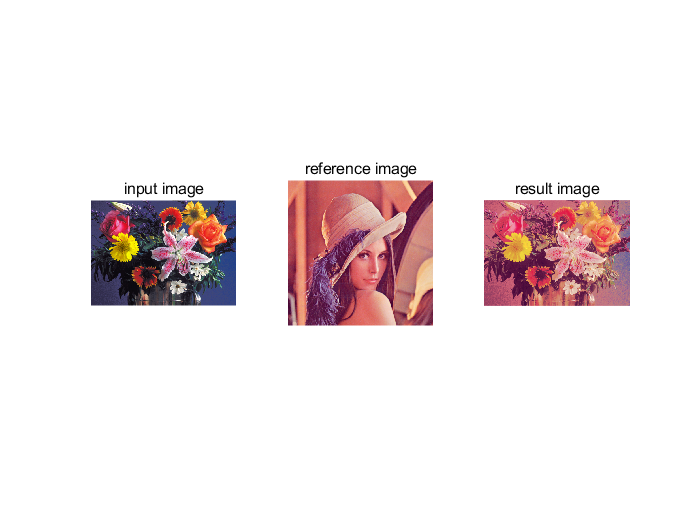

figure;
subplot(1, 3, 1); imshow(img_src); title('input image')
subplot(1, 3, 2); imshow(img_ref); title('reference image')
subplot(1, 3, 3); imshow(histsp); title('result image')

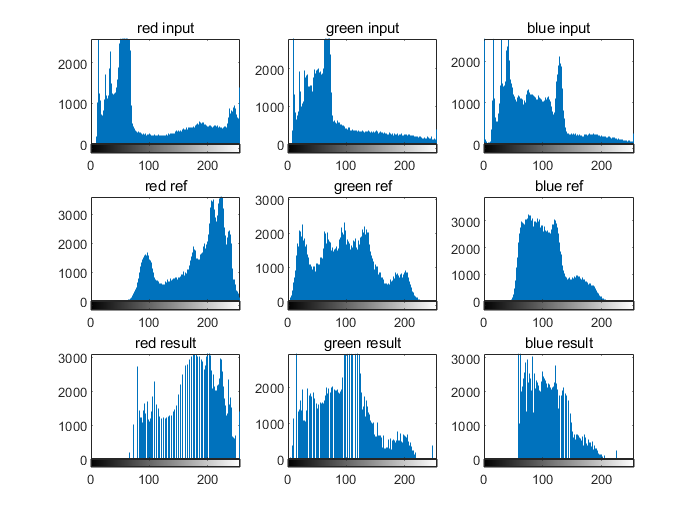

figure;
subplot(3, 3, 1); imhist(imgr1); title('red input')
subplot(3, 3, 2); imhist(imgg1); title('green input')
subplot(3, 3, 3); imhist(imgb1); title('blue input')
subplot(3, 3, 4); imhist(imgr2); title('red ref')
subplot(3, 3, 5); imhist(imgg2); title('green ref')
subplot(3, 3, 6); imhist(imgb2); title('blue ref')
subplot(3, 3, 7); imhist(outr); title('red result')
subplot(3, 3, 8); imhist(outg); title('green result')
subplot(3, 3, 9); imhist(outb); title('blue result')